## starting figures

load("automated_out.mat")
load("LAB_Results\R01_pid_emulation.mat")

#### dd plot of 1ms step responses: left model, right lab data, all discritizations and also continuous time overlapped in one plot

load(R01)

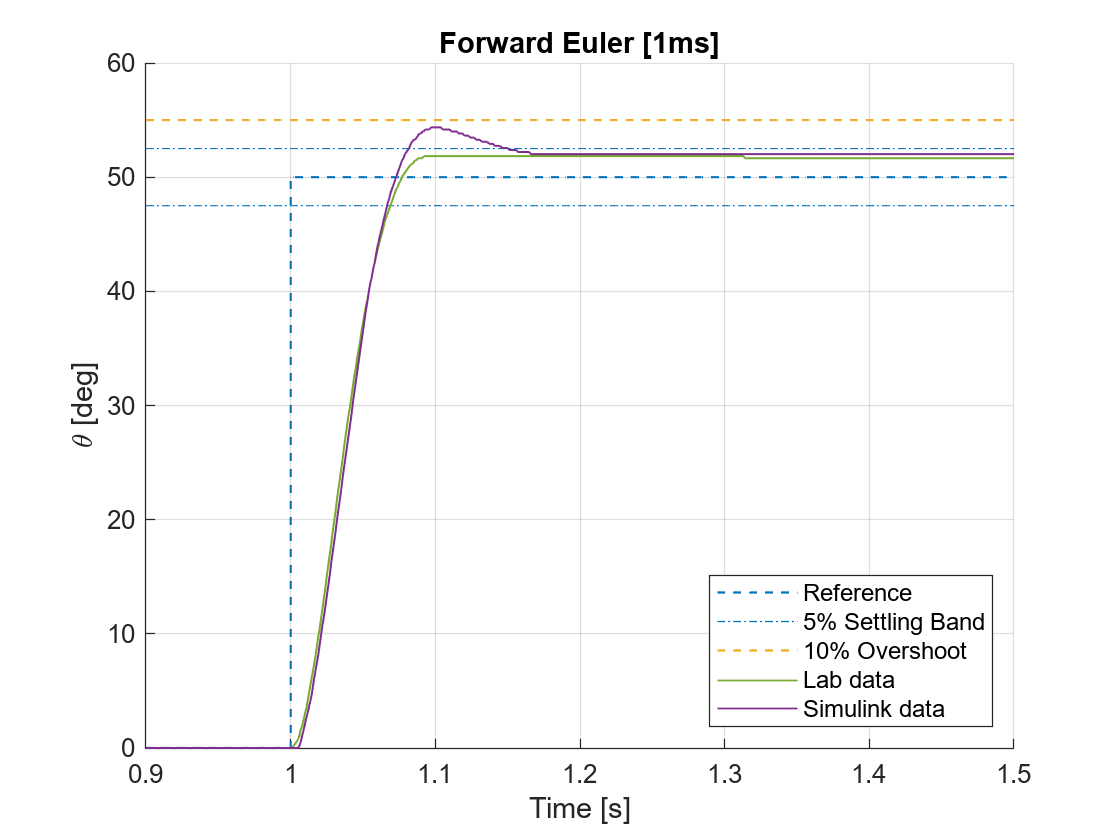

figure
hold on
% Ref
stairs(nominal_track.FE.T1.thref.time, nominal_track.FE.T1.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.FE.T1.thl_meas.time, nominal_track.FE.T1.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(pid_nominal_track.FE.T1.thl_meas.time, pid_nominal_track.FE.T1.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Lab data','Simulink data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Forward Euler [1ms]')
axis([0.9 1.5 0 60])
exportgraphics(gcf,'Figures\01_PID_01\FE.pdf','ContentType','vector')

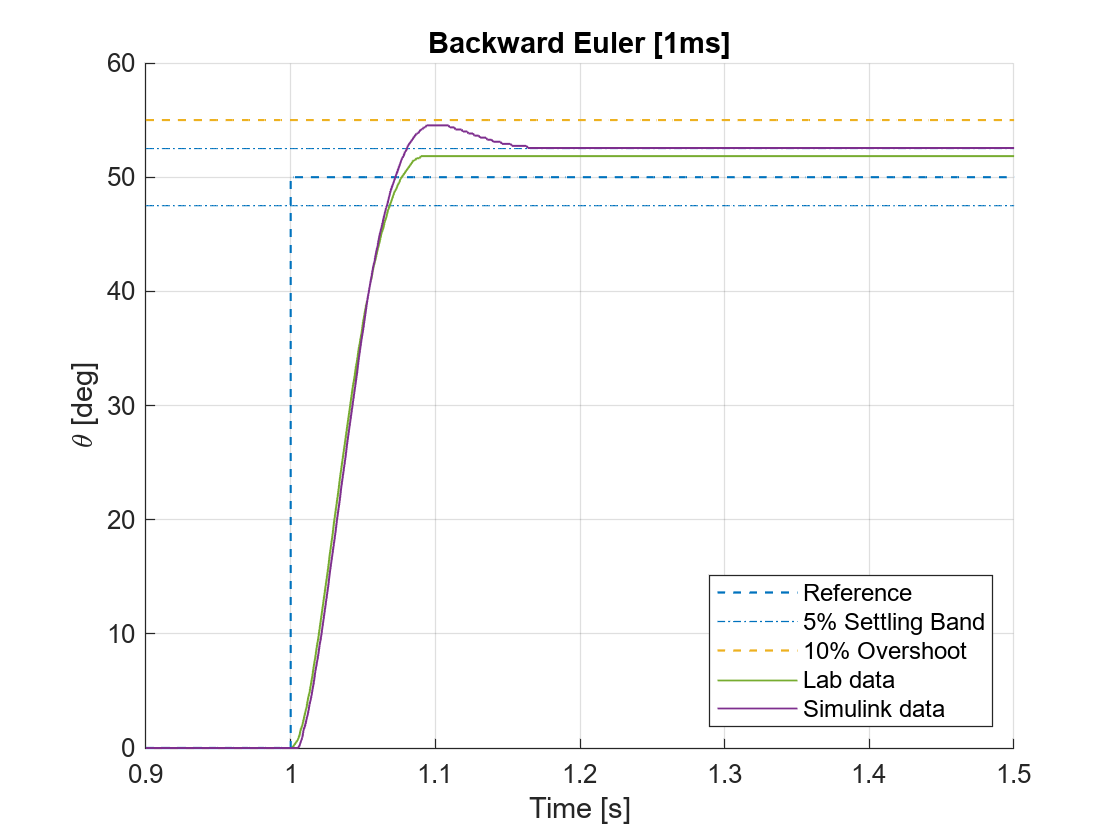

figure
hold on
% Ref
stairs(nominal_track.FE.T1.thref.time, nominal_track.FE.T1.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.BE.T1.thl_meas.time, nominal_track.BE.T1.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(pid_nominal_track.BE.T1.thl_meas.time, pid_nominal_track.BE.T1.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Lab data','Simulink data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Backward Euler [1ms]')
axis([0.9 1.5 0 60])
exportgraphics(gcf,'Figures\01_PID_01\BE.pdf','ContentType','vector')

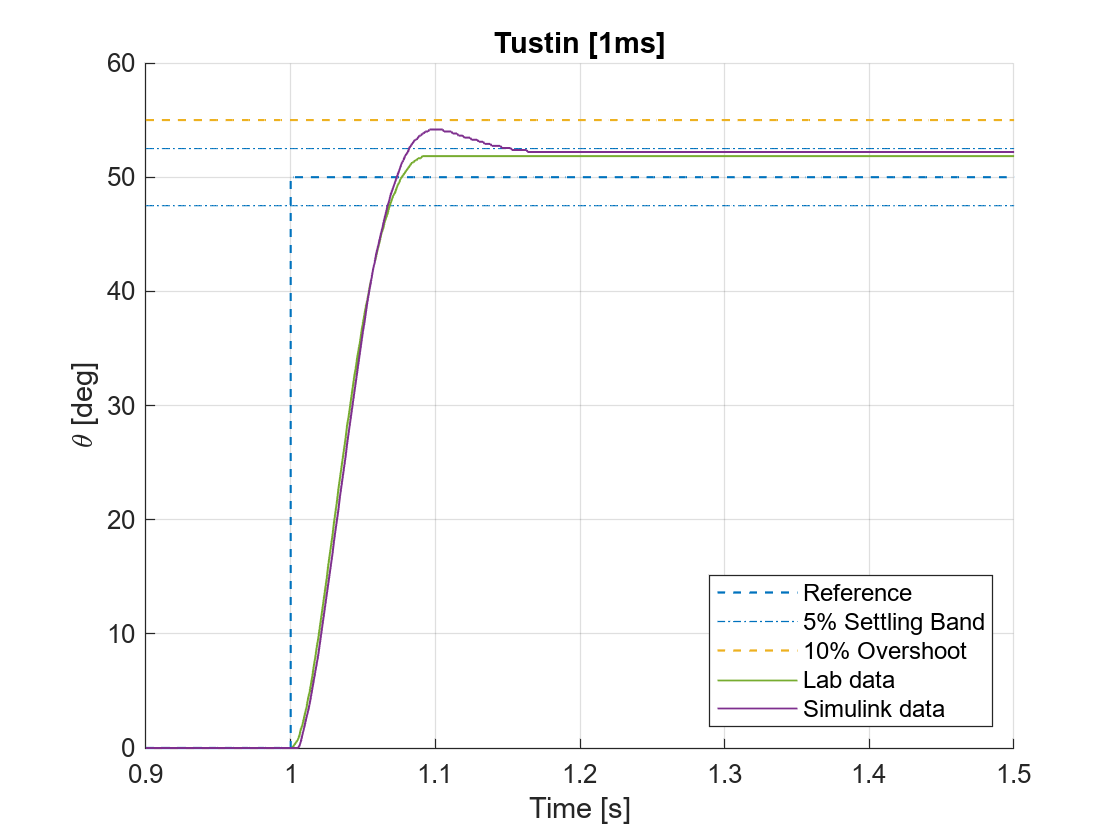

figure
hold on
% Ref
stairs(nominal_track.FE.T1.thref.time, nominal_track.FE.T1.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.TU.T1.thl_meas.time, nominal_track.TU.T1.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(pid_nominal_track.TU.T1.thl_meas.time, pid_nominal_track.TU.T1.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Lab data','Simulink data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Tustin [1ms]')
axis([0.9 1.5 0 60])
exportgraphics(gcf,'Figures\01_PID_01\tustin.pdf','ContentType','vector')

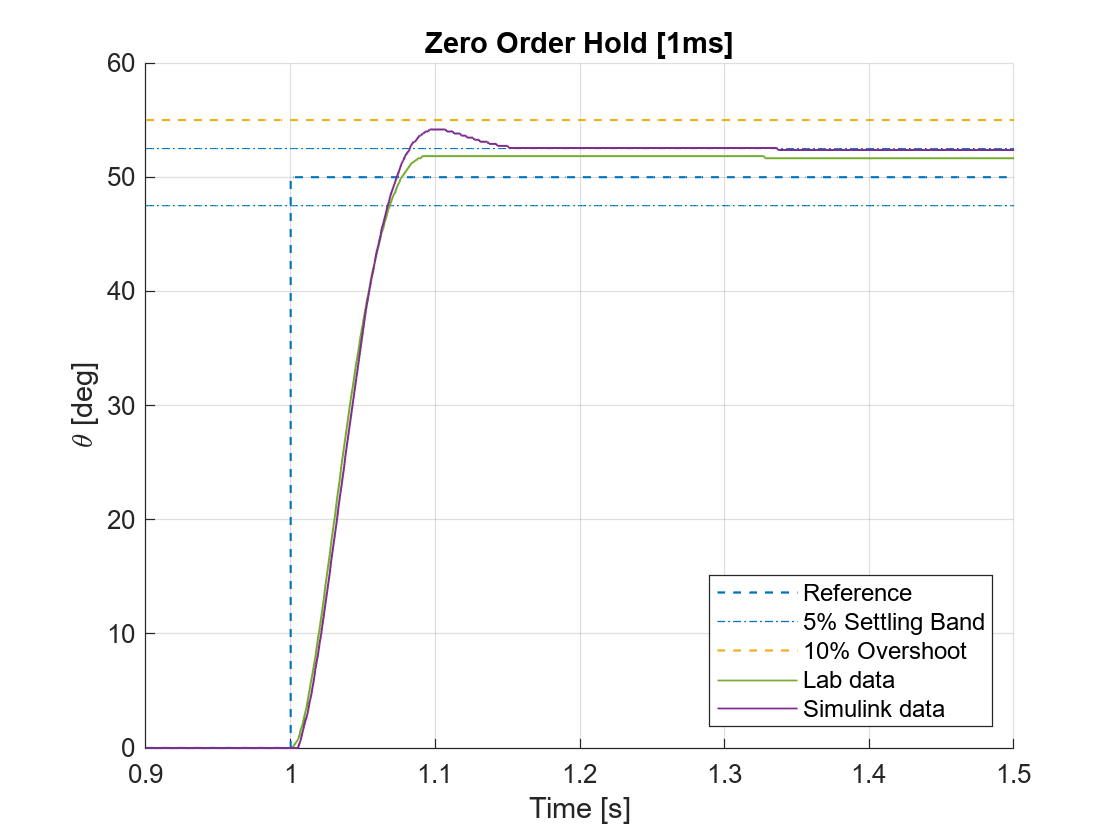

figure
hold on
% Ref
stairs(nominal_track.FE.T1.thref.time, nominal_track.FE.T1.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.TU.T1.thl_meas.time, nominal_track.ZOH.T1.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(pid_nominal_track.ZOH.T1.thl_meas.time, pid_nominal_track.ZOH.T1.thl_meas.signals.values,'LineWidth',0.7,'Color',"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Lab data','Simulink data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Zero Order Hold [1ms]')
axis([0.9 1.5 0 60])
exportgraphics(gcf,'Figures\01_PID_01\ZOH.pdf','ContentType','vector')

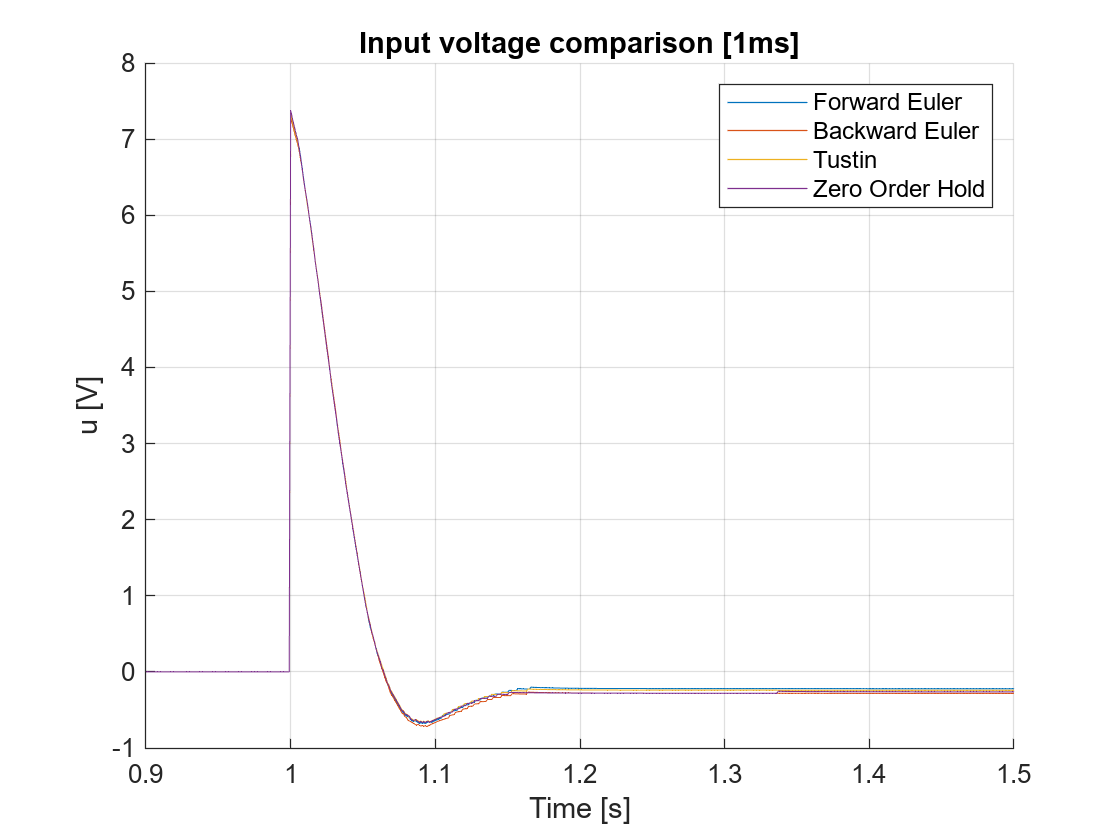

figure
hold on

plot(pid_nominal_track.FE.T1.thl_meas.time, pid_nominal_track.FE.T1.u.signals.values);
plot(pid_nominal_track.BE.T1.thl_meas.time, pid_nominal_track.BE.T1.u.signals.values);
plot(pid_nominal_track.TU.T1.thl_meas.time, pid_nominal_track.TU.T1.u.signals.values);
plot(pid_nominal_track.ZOH.T1.thl_meas.time, pid_nominal_track.ZOH.T1.u.signals.values);

legend('Forward Euler','Backward Euler','Tustin','Zero Order Hold','Location','northeast')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input voltage comparison [1ms]')
axis([0.9 1.5 -1 8])
exportgraphics(gcf,'Figures\01_PID_01\input_voltage.pdf','ContentType','vector')

#### zoh,FE in 2 plots beside each other, 50ms Lab data

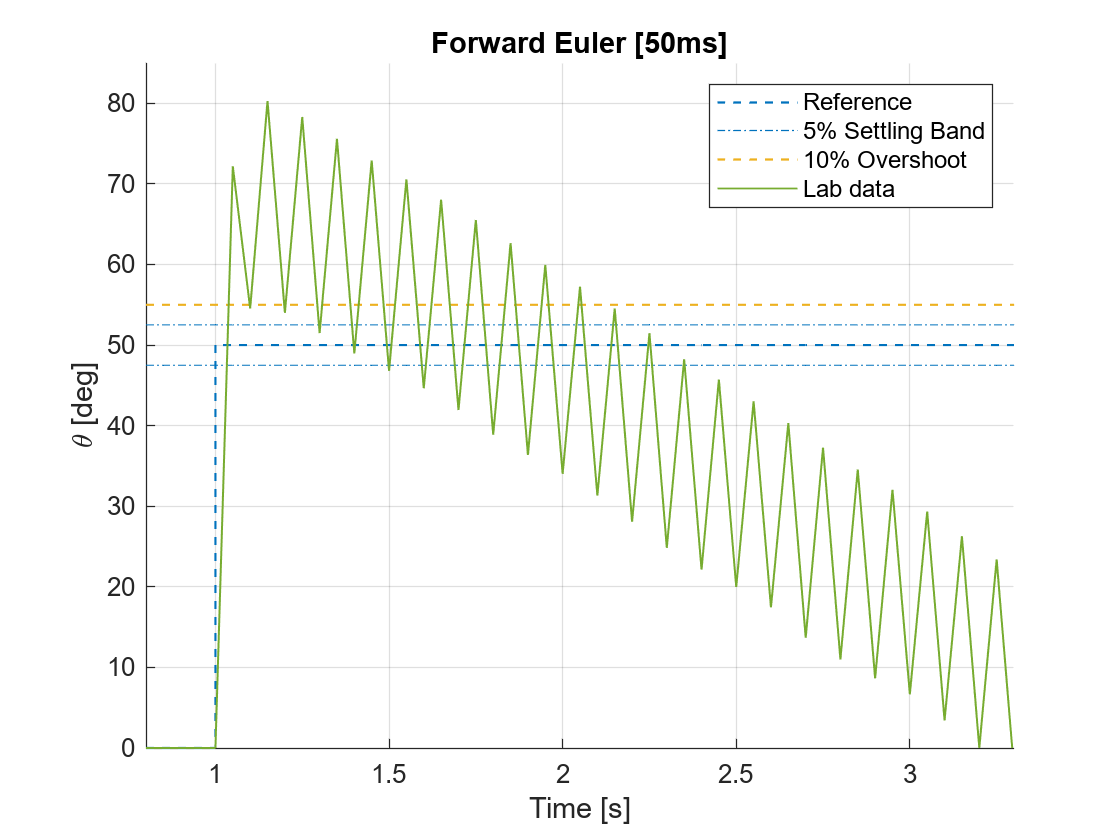

% Template to generate a figure
figure
hold on

% Ref
stairs(nominal_track.FE.T3.thref.time, nominal_track.FE.T3.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.FE.T3.thref.time-1, nominal_track.FE.T3.thref.signals.values*1.05,'-.','Color',"#0072BD" )
plot(nominal_track.FE.T3.thref.time-1, nominal_track.FE.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.FE.T3.thref.time-1, nominal_track.FE.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(pid_nominal_track.FE.T3.thl_meas.time, pid_nominal_track.FE.T3.thl_meas.signals.values,'LineWidth',0.7,'Color', '#77AC30')
% Legend
legend('Reference','5% Settling Band','','10% Overshoot', 'Lab data','Location','northeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Forward Euler [50ms]')
axis([0.8 3.3 0 85])
exportgraphics(gcf,'Figures\02_PID_50_FE_ZOH\FE_lab.pdf','ContentType','vector')

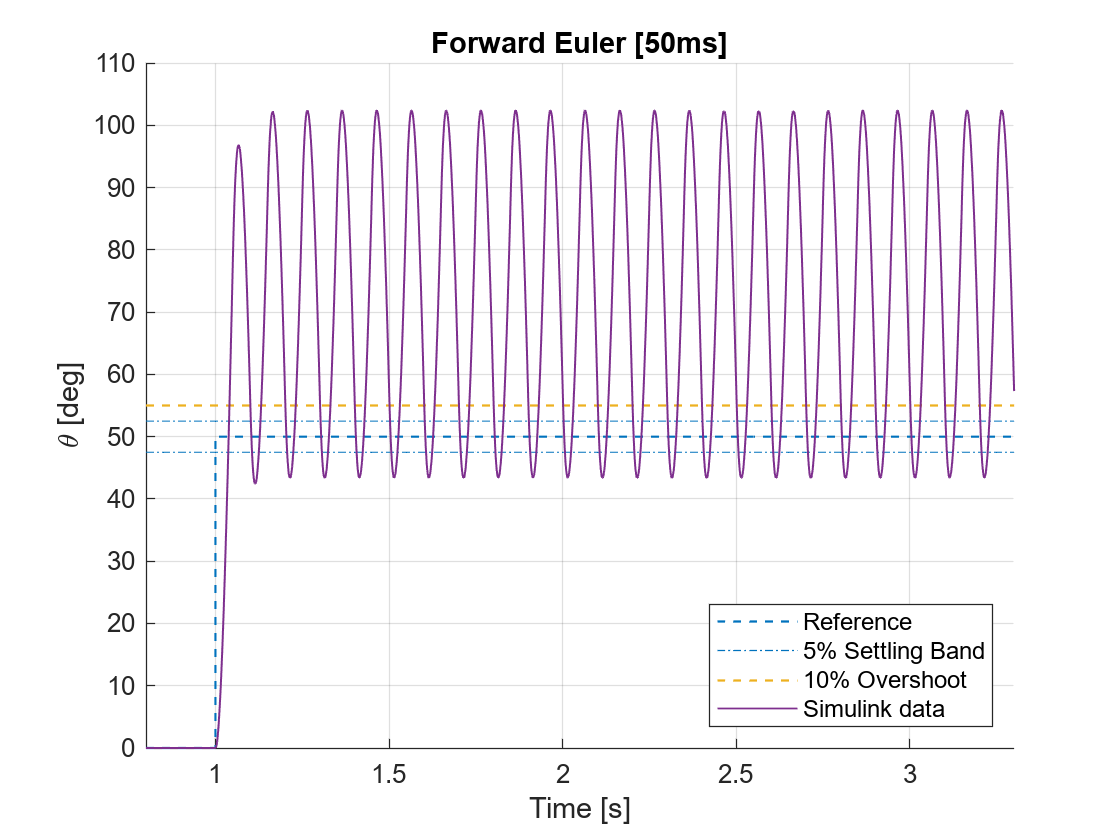

% Template to generate a figure
figure
hold on

% Ref
stairs(nominal_track.FE.T3.thref.time, nominal_track.FE.T3.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.FE.T3.thref.time-1, nominal_track.FE.T3.thref.signals.values*1.05,'-.','Color',"#0072BD" )
plot(nominal_track.FE.T3.thref.time-1, nominal_track.FE.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.FE.T3.thref.time-1, nominal_track.FE.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.FE.T3.thl_meas.time, nominal_track.FE.T3.thl_meas.signals.values,'LineWidth',0.7, 'Color', "#7E2F8E")

% Legend
legend('Reference','5% Settling Band','','10% Overshoot', 'Simulink data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Forward Euler [50ms]')
axis([0.8 3.3 0 110])
exportgraphics(gcf,'Figures\02_PID_50_FE_ZOH\FE_sim.pdf','ContentType','vector')

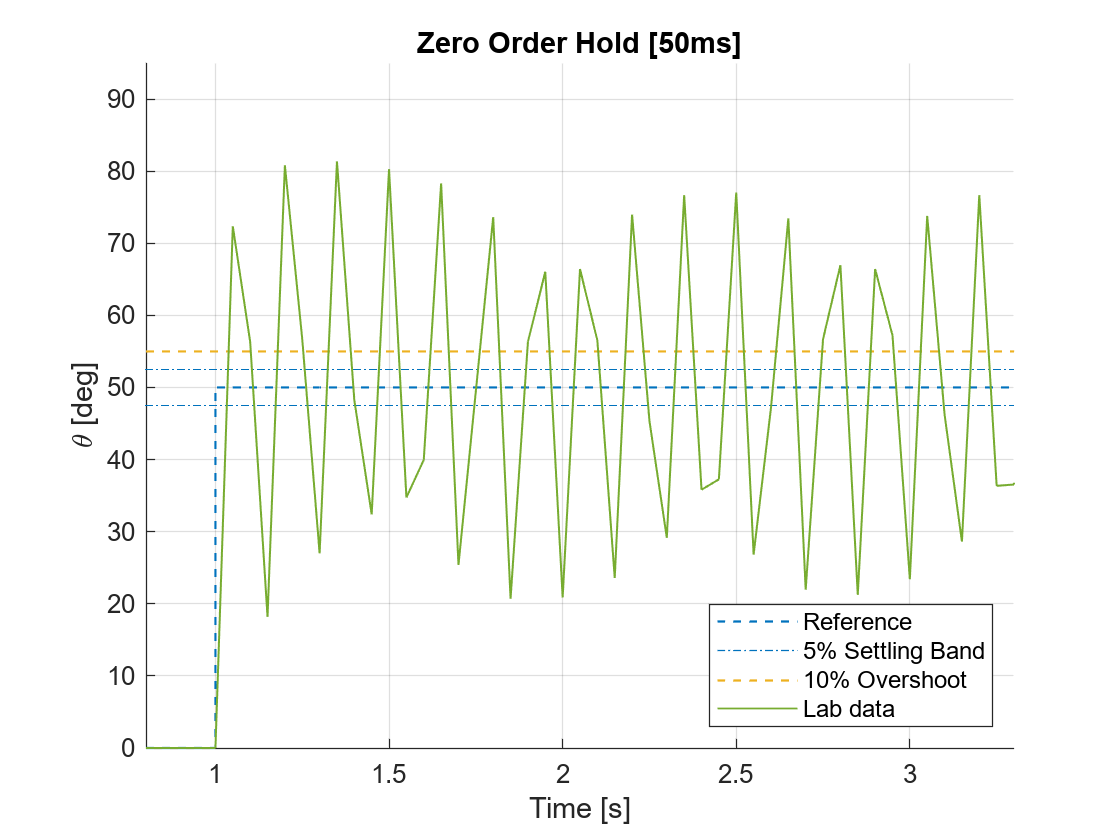

% Template to generate a figure
figure
hold on
% Ref
stairs(nominal_track.ZOH.T3.thref.time, nominal_track.ZOH.T3.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.ZOH.T3.thref.time-1, nominal_track.ZOH.T3.thref.signals.values*1.05,'-.','Color',"#0072BD" )
plot(nominal_track.ZOH.T3.thref.time-1, nominal_track.ZOH.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.ZOH.T3.thref.time-1, nominal_track.ZOH.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(pid_nominal_track.ZOH.T3.thl_meas.time, pid_nominal_track.ZOH.T3.thl_meas.signals.values,'LineWidth',0.7,'Color', '#77AC30')

% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Lab data','Location','southeast')

grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Zero Order Hold [50ms]')
axis([0.8 3.3 0 95])
exportgraphics(gcf,'Figures\02_PID_50_FE_ZOH\ZOH_lab.pdf','ContentType','vector')

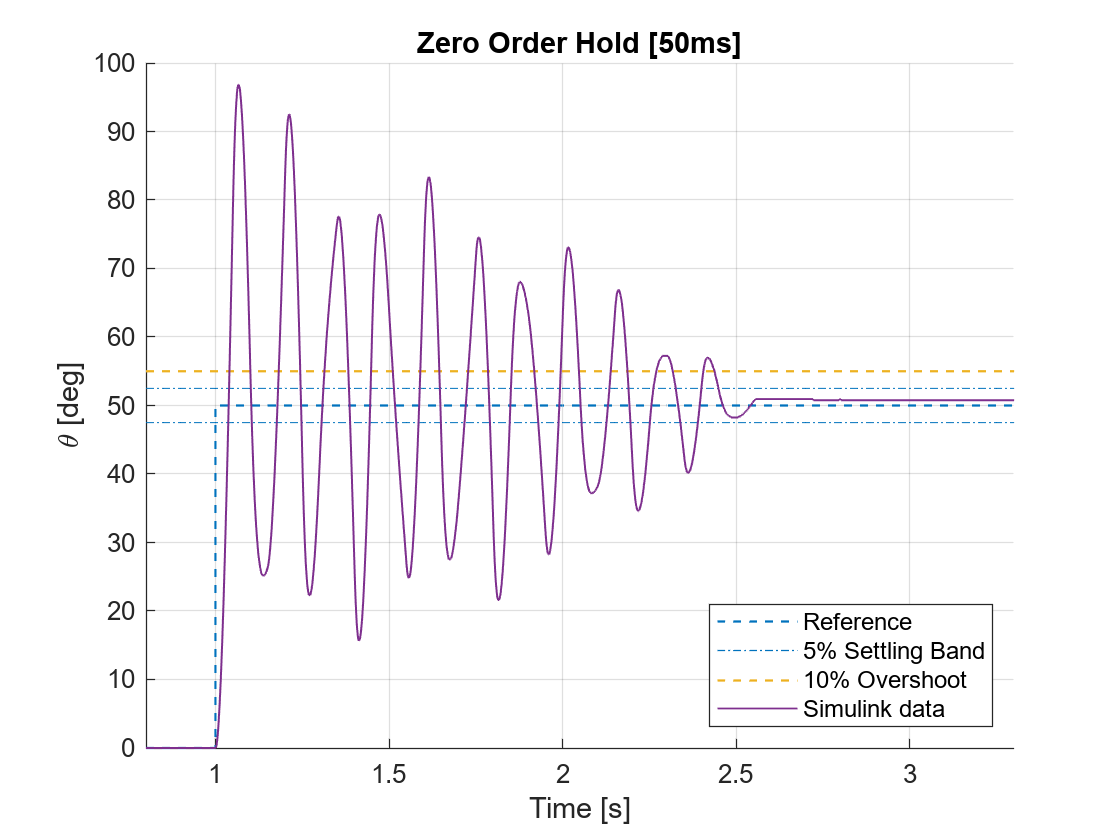

figure
hold on
% Ref
stairs(nominal_track.ZOH.T3.thref.time, nominal_track.ZOH.T3.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.ZOH.T3.thref.time-1, nominal_track.ZOH.T3.thref.signals.values*1.05,'-.','Color',"#0072BD" )
plot(nominal_track.ZOH.T3.thref.time-1, nominal_track.ZOH.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.ZOH.T3.thref.time-1, nominal_track.ZOH.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.ZOH.T3.thl_meas.time, nominal_track.ZOH.T3.thl_meas.signals.values,'LineWidth',0.7, 'Color',  "#7E2F8E")

% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Location','southeast')

grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Zero Order Hold [50ms]')
axis([0.8 3.3 0 100])
exportgraphics(gcf,'Figures\02_PID_50_FE_ZOH\ZOH_sim.pdf','ContentType','vector')

#### 1 Plot - BE,tust,continous 50ms Lab data 

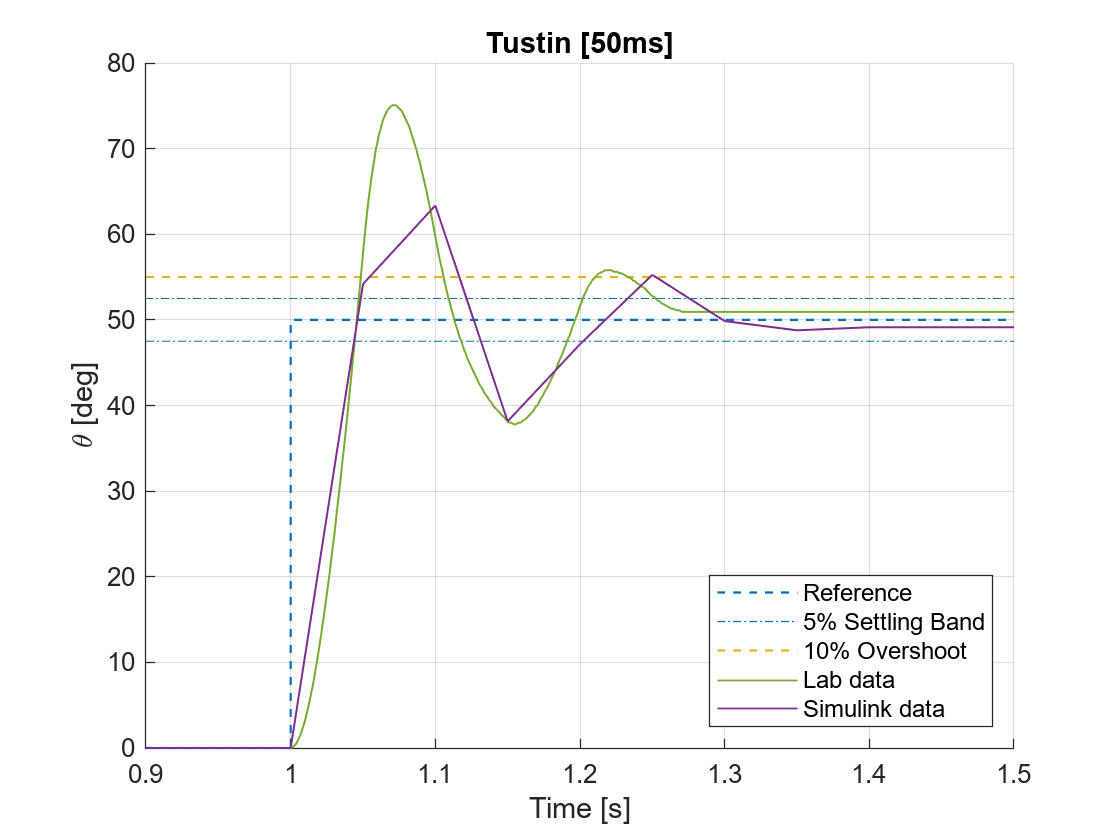

figure
hold on
% Ref
stairs(nominal_track.TU.T3.thref.time, nominal_track.TU.T3.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.TU.T3.thref.time-1, nominal_track.TU.T3.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(nominal_track.TU.T3.thref.time-1, nominal_track.TU.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.TU.T3.thref.time-1, nominal_track.TU.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.TU.T3.thl_meas.time, nominal_track.TU.T3.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(pid_nominal_track.TU.T3.thl_meas.time, pid_nominal_track.TU.T3.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Lab data','Simulink data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Tustin [50ms]')
axis([0.9 1.5 0 80])
exportgraphics(gcf,'Figures\03_PID_50_TU_BE\tustin.pdf','ContentType','vector')

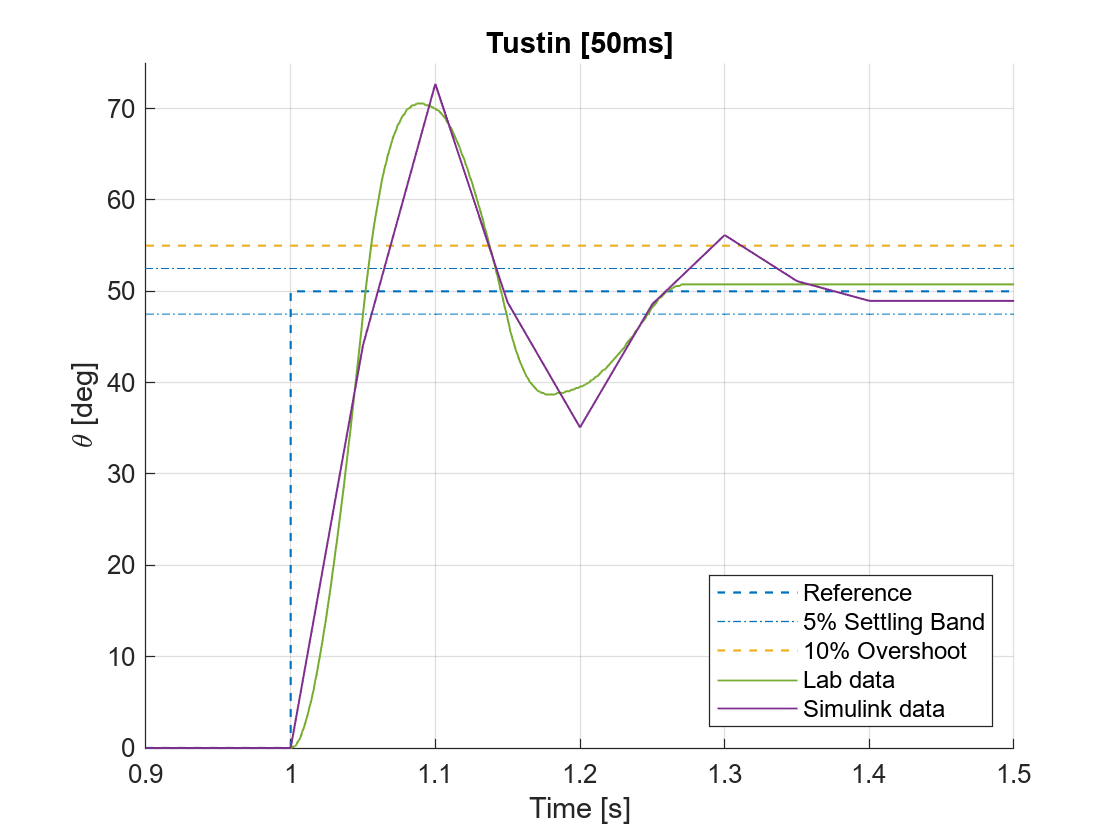


figure
hold on
% Ref
stairs(nominal_track.BE.T3.thref.time, nominal_track.BE.T3.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.BE.T3.thref.time-1, nominal_track.BE.T3.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(nominal_track.BE.T3.thref.time-1, nominal_track.BE.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.BE.T3.thref.time-1, nominal_track.BE.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.BE.T3.thl_meas.time, nominal_track.BE.T3.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(pid_nominal_track.BE.T3.thl_meas.time, pid_nominal_track.BE.T3.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Lab data','Simulink data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Tustin [50ms]')
axis([0.9 1.5 0 75])
exportgraphics(gcf,'Figures\03_PID_50_TU_BE\BE.pdf','ContentType','vector')

1 no awu, CT(BB) and BE (Lab data) 10 ms

1 awu, CT (BB) and BE (Lab data) 10 ms

load("LAB_Results\R02_pid_awu.mat")

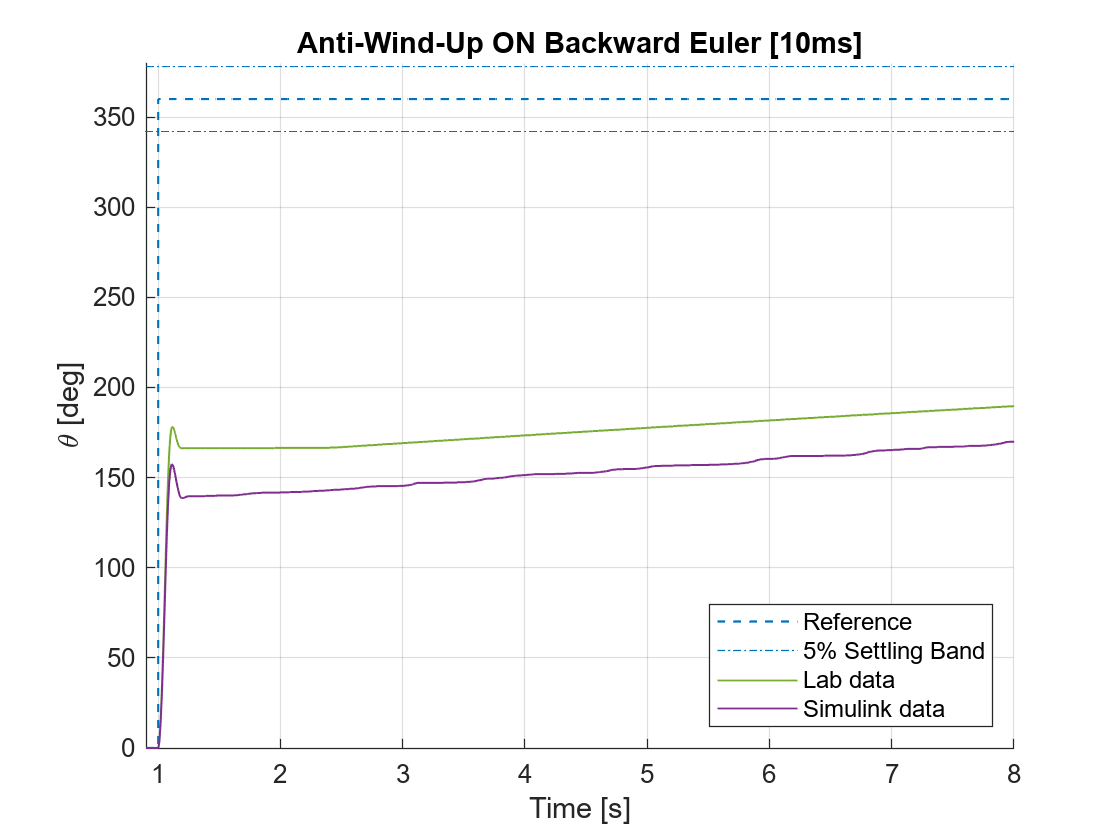

figure
hold on
% Ref
stairs(pid_nominal_track.AWU.BE.thref.time, pid_nominal_track.AWU.BE.thref.signals.values,'--','LineWidth',0.8)
plot(pid_nominal_track.AWU.BE.thref.time-1, pid_nominal_track.AWU.BE.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(pid_nominal_track.AWU.BE.thref.time-1, pid_nominal_track.AWU.BE.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(pid_nominal_track.AWU.BE.thref.time-1, pid_nominal_track.AWU.BE.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.AWU.BE.thl_meas.time, nominal_track.AWU.BE.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(pid_nominal_track.AWU.BE.thl_meas.time, pid_nominal_track.AWU.BE.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','','Lab data','Simulink data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Anti-Wind-Up ON Backward Euler [10ms]')
axis([0.9 8 0 380])
exportgraphics(gcf,'Figures\04_PID_AWU\awu_BE.pdf','ContentType','vector')

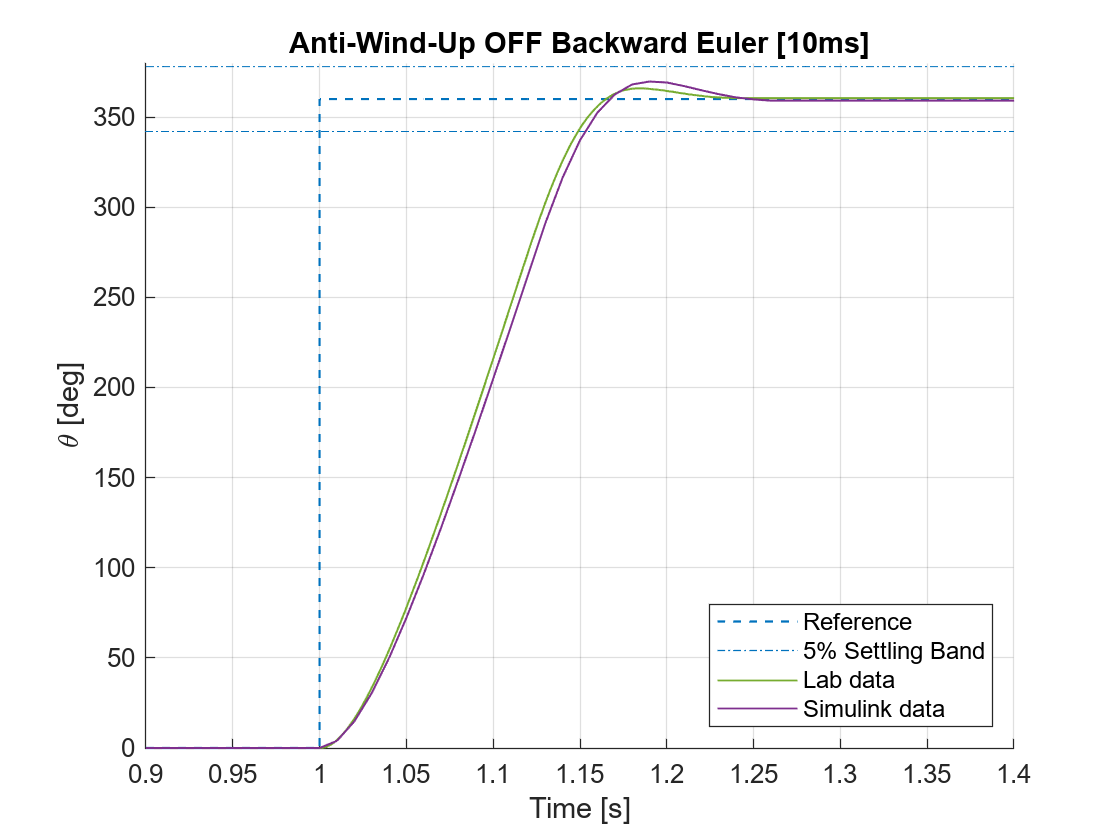

figure
hold on
% Ref
stairs(pid_nominal_track.NOAWU.BE.thref.time, pid_nominal_track.NOAWU.BE.thref.signals.values,'--','LineWidth',0.8)
plot(pid_nominal_track.NOAWU.BE.thref.time-1, pid_nominal_track.NOAWU.BE.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(pid_nominal_track.NOAWU.BE.thref.time-1, pid_nominal_track.NOAWU.BE.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(pid_nominal_track.NOAWU.BE.thref.time-1, pid_nominal_track.NOAWU.BE.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.NOAWU.BE.thl_meas.time, nominal_track.NOAWU.BE.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(pid_nominal_track.NOAWU.BE.thl_meas.time, pid_nominal_track.NOAWU.BE.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','','Lab data','Simulink data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Anti-Wind-Up OFF Backward Euler [10ms]')
axis([0.9 1.4 0 380])
exportgraphics(gcf,'Figures\04_PID_AWU\no_awu_BE.pdf','ContentType','vector')

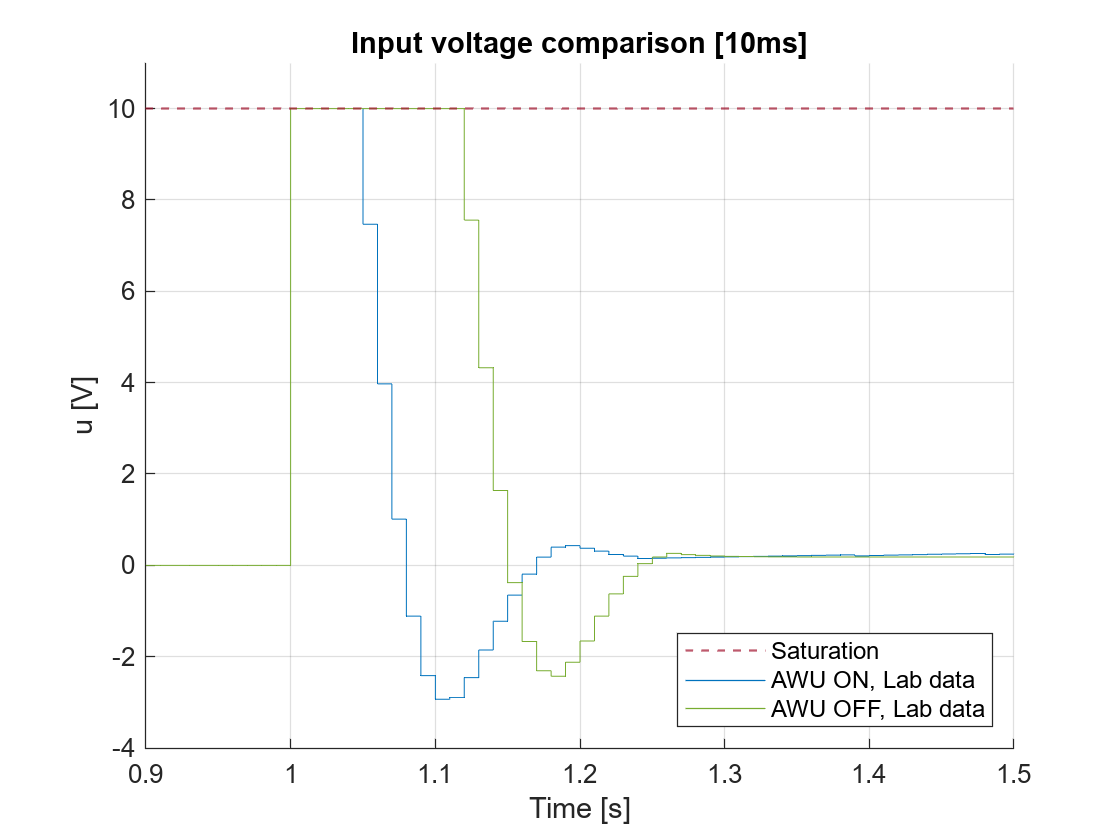


figure
hold on

yline(10, '--','Color',	"#A2142F",'LineWidth',0.8)
stairs(pid_nominal_track.AWU.BE.thl_meas.time, pid_nominal_track.AWU.BE.u.signals.values ,'Color',	'#0072BD')
stairs(pid_nominal_track.NOAWU.BE.thl_meas.time, pid_nominal_track.NOAWU.BE.u.signals.values ,'Color',	"#77AC30");


legend('Saturation', 'AWU ON, Lab data','AWU OFF, Lab data', 'Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input voltage comparison [10ms]')
axis([0.9 1.5 -4 11])
exportgraphics(gcf,'Figures\04_PID_AWU\input_voltage.pdf','ContentType','vector')

1 Plot: FF BE 10ms Lab data, No FF BE 10ms corbioli Tracking error FF vs no FF 

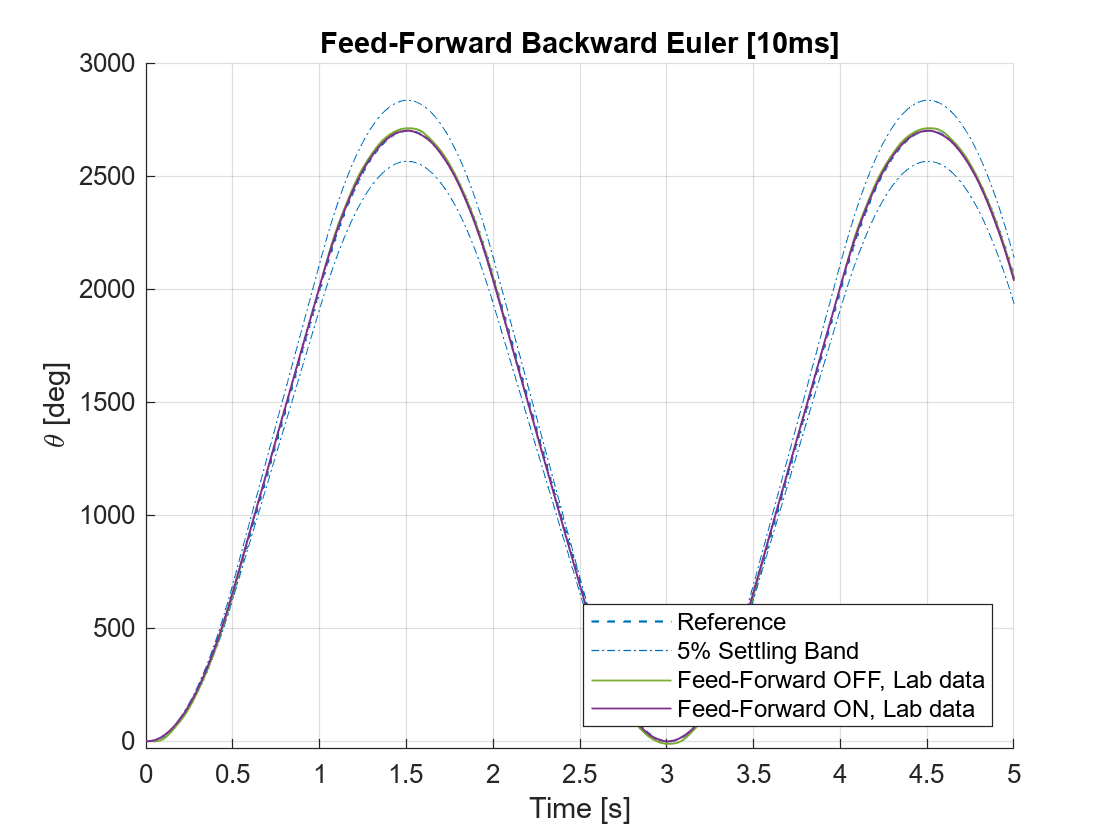

load("LAB_Results\corby\RealSim3113_feedForward.mat")
lab.no_ff=out_no_ff;
lab.ff=out_ff;
load("LAB_Results\corby\SIM2113_PID_feedForward.mat")
manual.no_ff=out_no_ff;
manual.ff=out_ff;


figure
hold on
% Ref
stairs(lab.no_ff.thl_ref.time, lab.no_ff.thl_ref.signals.values,'--','LineWidth',0.8)
plot(lab.no_ff.thl_ref.time, lab.no_ff.thl_ref.signals.values*1.05,'-.','Color',"#0072BD")
plot(lab.no_ff.thl_ref.time, lab.no_ff.thl_ref.signals.values*0.95,'-.','Color',"#0072BD")
%plot(lab.no_ff.thl_ref.time, lab.no_ff.thl_ref.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(lab.no_ff.thl_meas.time, lab.no_ff.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(lab.ff.thl_meas.time, lab.ff.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','Feed-Forward OFF, Lab data','Feed-Forward ON, Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Feed-Forward Backward Euler [10ms]')
axis([0 5 -30 3000])
exportgraphics(gcf,'Figures\05_PID_FFW\ffw_comparison.pdf','ContentType','vector')

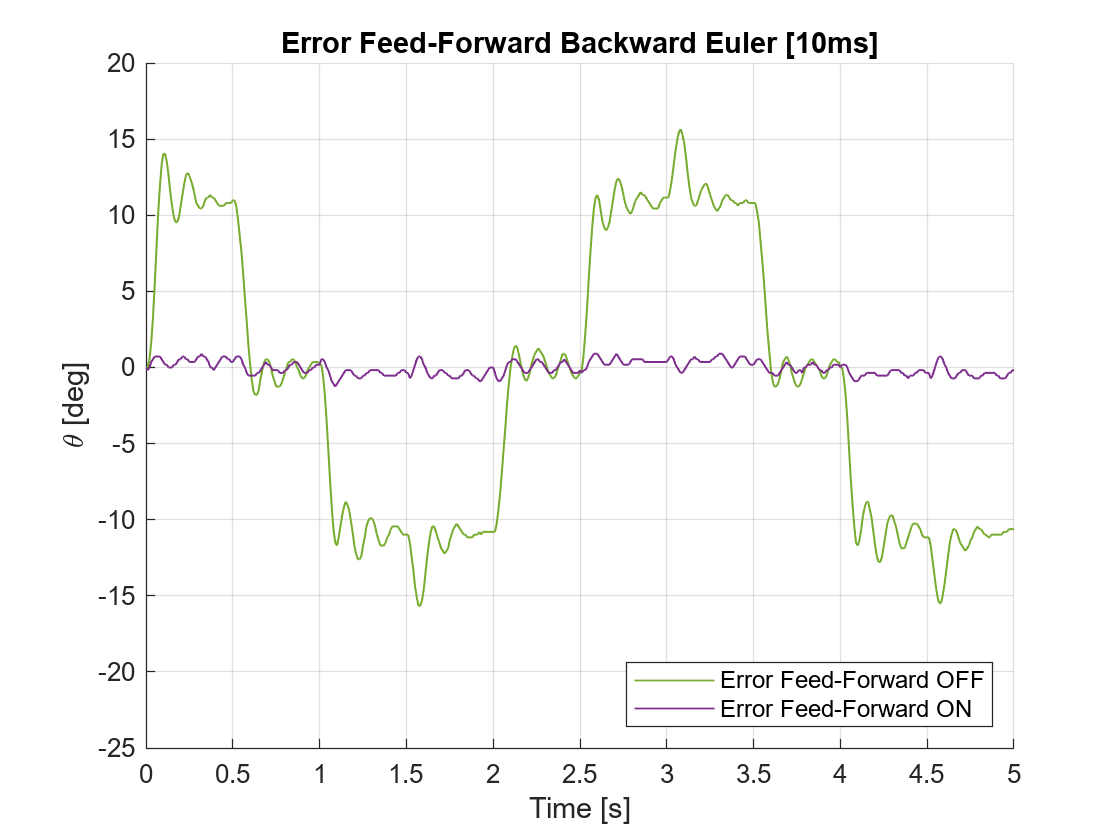


figure
hold on
% Data
plot(lab.no_ff.thl_meas.time, lab.no_ff.thl_ref.signals.values-lab.no_ff.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(lab.ff.thl_meas.time, lab.ff.thl_ref.signals.values-lab.ff.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Error Feed-Forward OFF','Error Feed-Forward ON','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Error Feed-Forward Backward Euler [10ms]')
axis([0 5 -25 20])
exportgraphics(gcf,'Figures\05_PID_FFW\ffw_error.pdf','ContentType','vector')